# Solar House

clf 
days = 60;
tspan = linspace(0,days*60*60*24,10*60*60*24); %0, sec*hours*day ,10 days*sec in an hour*min in an hour*hours in a day


%air
y_0= 21; %start temp 
T_air = -3; %temp of air constant

%floor
x_floor = 5; %m
y_floor = .3; %m
z_floor = 5; %m
m_floor = 3000 * x_floor * z_floor* y_floor; %kg thermal mass of floor
c_floor = 800; % j/kgK
A_floor = x_floor*z_floor; %m^2 surface area of the floor

%window
y_win = 2.6; %m
z_win = 2.5; %m
A_win = y_win * z_win; %m^2
h_win = 1.4; % w/m2-k Effective heat transfer coefficient of double-paned window. 
c_win = 700; %j/kg-k

%wall
y_wall = 20; %m
x_wall = 5.1; %m
z_wall = 5; %m
L_wall = .2; %wall thickness
A_wallin = 2*(x_wall * z_wall) + 2*(y_wall*z_wall)-A_win; %m2 surface area of the wall inside the house
c_wall = 800;
k_wall = 0.04; %a of fiberglass insulation (0.04 W/m-K)


h_inside = 15; %heat transfer coefficient inside
h_outside = 30; %heat transfer coefficient outside


### Thermal Resistance

For convection (characterized by heat transfer coefficient h) between a liquid or gas and a solid surface with surface area A (A is the surface area exposed to the fluid), the thermal convection resistance Rconv is:


$$R_{\mathrm{conv}} =\frac{1}{\mathrm{hA}}$$


For (relatively steady) conduction through a material with thermal conductivity k, cross-sectional area A (i.e., area perpendicular to heat flow) and thickness L, the thermal conduction resistance Rcond is: 


$$R_{\textrm{cond}} =\frac{L}{\textrm{kA}}$$


%Floor Thermal Resisitance Equations
TR_FloortoAir = 1/(h_inside * A_floor);

%Wall Thermal Resisitance Equations
TR_Wall  = L_wall/(k_wall * A_wallin);
TR_AirtoWall_out = 1/(h_outside * A_wallin); 
TR_AirtoWall_in = 1/(h_inside * A_wallin);

%Window Thermal Resisitance Equations
TR_AirtoWin_in = 1/(h_inside*A_win);
TR_Win   = 1/(h_win*A_win);
TR_AirtoWin_out = 1/(h_outside*A_win);

#### Total Thermal Resistance

The thermal resistance network is a graphical way of depicting how these two heat flow paths are in parallel, but that within each path there are resistances in series; each node represents a surface or fluid at a particular temperature. R1, R3, R4, and R6 are convection resistances, while R2 and R5 are conduction resistances. The equivalent circuit (a single resistor) for this mug is also shown. The equivalent resistance for heat loss from the tea to the outside world can be expressed as two parallel sets of resistors-in-series: 

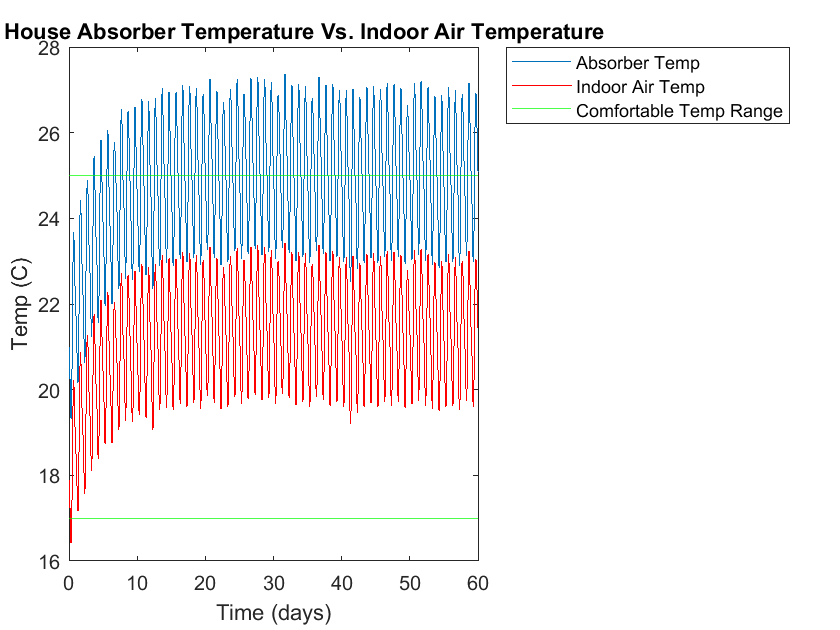

%TR_total = Thermal Resistance of floor to air + the lump sum thermal
%resistance of the rest of the house
TR_total = TR_FloortoAir + 1/((1/(TR_AirtoWall_in + TR_Wall + TR_AirtoWall_out)) + (1/(TR_AirtoWin_in + TR_Win + TR_AirtoWin_out))); %thermal resistance

%Refrence equations
%q = (-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) +210)
%Q_in_sun = q * A_win

%dT_final/dt = Q_in_sun/(m_floor*c_floor) - (T_floor - T_air)/(TR_total*m_floor*c_floor);
[t, y] = ode45(@(t,y) A_win*(-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) + 210)/(m_floor*c_floor) - (y - T_air)/(TR_total*m_floor*c_floor), tspan, y_0);

T_air_in = ((-TR_FloortoAir.*(y - T_air))./TR_total) + y;



plot(t/(60*60*24),y)
hold on
plot(t/(60*60*24),T_air_in, 'red')
yline(17,'green')
yline(25, 'green')
xlabel("Time (days)")
ylabel("Temp (C)")
legend('Absorber Temp', 'Indoor Air Temp', 'Comfortable Temp Range',"Location","bestoutside")
title('Solar House Absorber Temperature Vs. Indoor Air Temperature')

.

## Absorber(Floor) Thickness Sweep

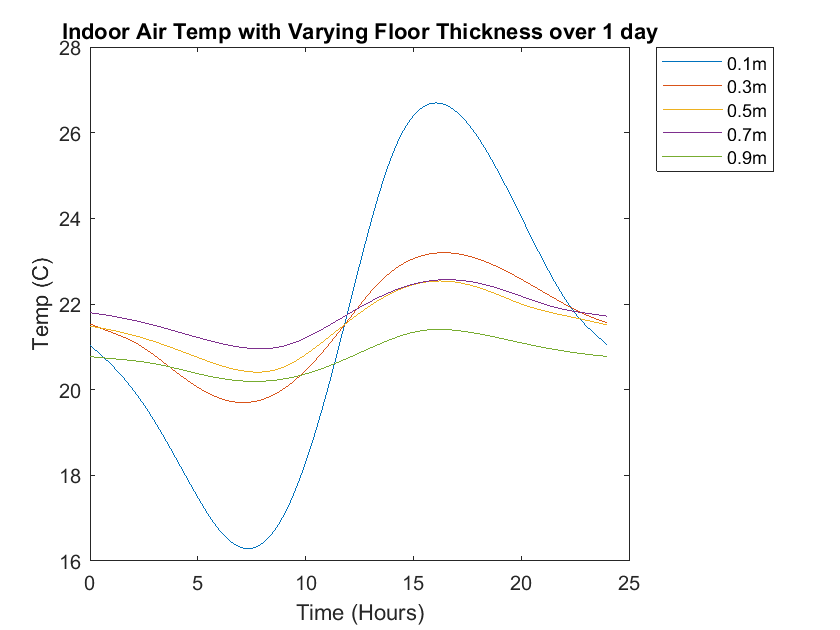

figure
for y_floor = .1:.2:.9 %floor thickness
    m_floor = 3000 * x_floor * z_floor* y_floor; %kg thermal mass of floor
   
    %Refrence equations
    %q = (-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) +21 0)
    %Q_in_sun = q * A_win

    %dT_final/dt = Q_in_sun/(m_floor*c_floor) - (T_floor - T_air)/(TR_total*m_floor*c_floor);
    [t, y] = ode45(@(t,y) A_win*(-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) + 210)/(m_floor*c_floor) - (y - T_air)/(TR_total*m_floor*c_floor), tspan, y_0);

    T_air_in = ((-TR_FloortoAir.*(y - T_air))./TR_total) + y;
   
    dayfourtynine = 48*60*60*24/6;
    dayfifty = 49*60*60*24/6;

    plot((t(dayfourtynine:dayfifty)-t(dayfourtynine))/(60*60), T_air_in(dayfourtynine:dayfifty))
    hold on
    legend('0.1m','0.3m','0.5m','0.7m','0.9m',"Location","bestoutside")
    xlabel("Time (Hours)")
    ylabel("Temp (C)")
    title('Indoor Air Temp with Varying Floor Thickness over 1 day')
end

% yline(17,'g')
% yline(25, 'g')


## Wall Thickness Sweep

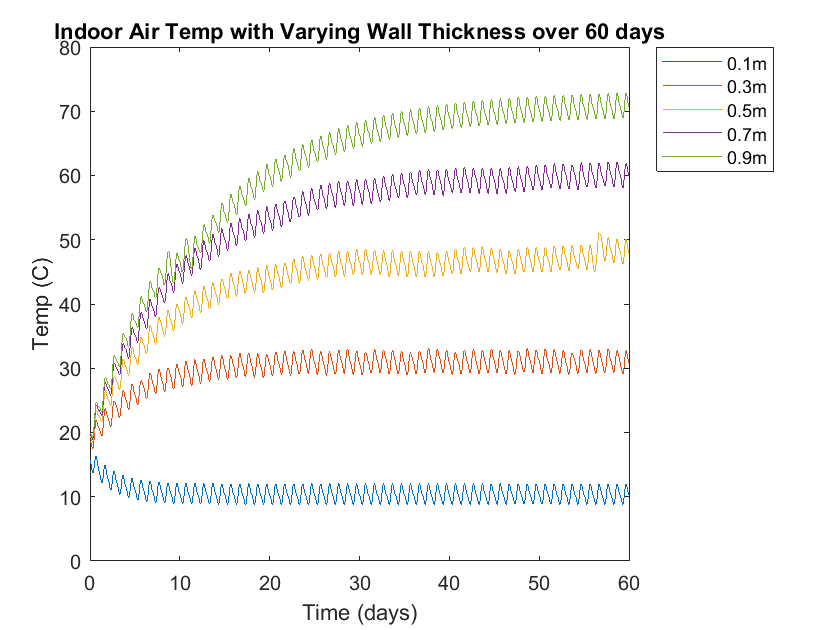

figure
for L_wall = .1:.2:.9
    TR_Wall  = L_wall/(k_wall * A_wallin);
    TR_total = TR_FloortoAir + 1/((1/(TR_AirtoWall_in + TR_Wall + TR_AirtoWall_out)) + (1/(TR_AirtoWin_in + TR_Win + TR_AirtoWin_out))); %thermal resistance

    %Refrence equations
    %q = (-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) +21 0)
    %Q_in_sun = q * A_win

    %dT_final/dt = Q_in_sun/(m_floor*c_floor) - (T_floor - T_air)/(TR_total*m_floor*c_floor);
    [t, y] = ode45(@(t,y) A_win*(-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) + 210)/(m_floor*c_floor) - (y - T_air)/(TR_total*m_floor*c_floor), tspan, y_0);

    T_air_in = ((-TR_FloortoAir.*(y - T_air))./TR_total) + y;
   

    plot(t/(60*60*24),T_air_in)
    hold on
    legend('0.1m','0.3m','0.5m','0.7m','0.9m',"Location","bestoutside")
    xlabel("Time (days)")
    ylabel("Temp (C)")
    title('Indoor Air Temp with Varying Wall Thickness over 60 days')
end

% yline(17,'g')
% yline(25, 'g')


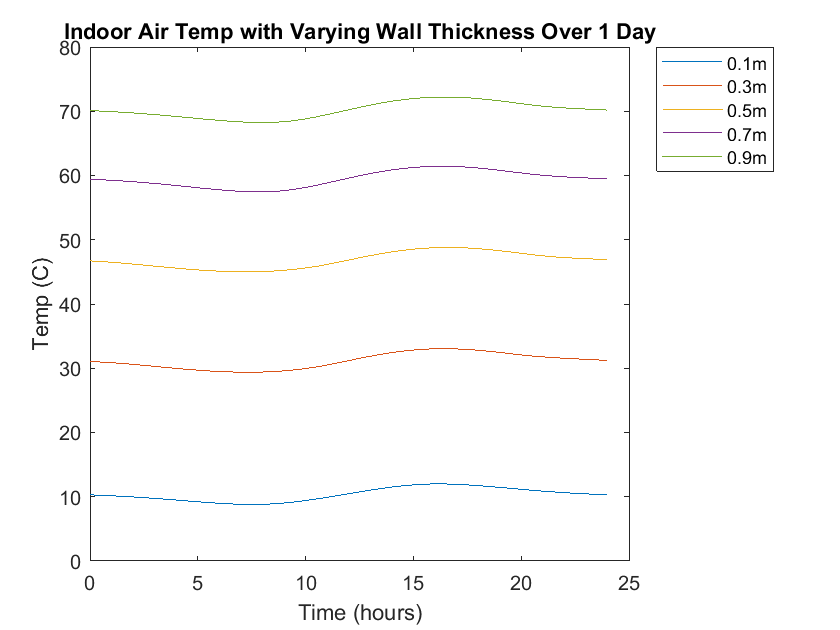


figure
for L_wall = .1:.2:.9
    TR_Wall  = L_wall/(k_wall * A_wallin);
    TR_total = TR_FloortoAir + 1/((1/(TR_AirtoWall_in + TR_Wall + TR_AirtoWall_out)) + (1/(TR_AirtoWin_in + TR_Win + TR_AirtoWin_out))); %thermal resistance

    %Refrence equations
    %q = (-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) +21 0)
    %Q_in_sun = q * A_win

    %dT_final/dt = Q_in_sun/(m_floor*c_floor) - (T_floor - T_air)/(TR_total*m_floor*c_floor);
    [t, y] = ode45(@(t,y) A_win*(-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) + 210)/(m_floor*c_floor) - (y - T_air)/(TR_total*m_floor*c_floor), tspan, y_0);

    T_air_in = ((-TR_FloortoAir.*(y - T_air))./TR_total) + y;
    
    dayfourtynine = 48*60*60*24/6;
    dayfifty = 49*60*60*24/6;

    plot((t(dayfourtynine:dayfifty)-t(dayfourtynine))/(60*60), T_air_in(dayfourtynine:dayfifty))
    hold on
    legend('0.1m','0.3m','0.5m','0.7m','0.9m',"Location","bestoutside")
    xlabel("Time (hours)")
    ylabel("Temp (C)")
    title('Indoor Air Temp with Varying Wall Thickness Over 1 Day')
end

## Thermal Conductivity Sweep

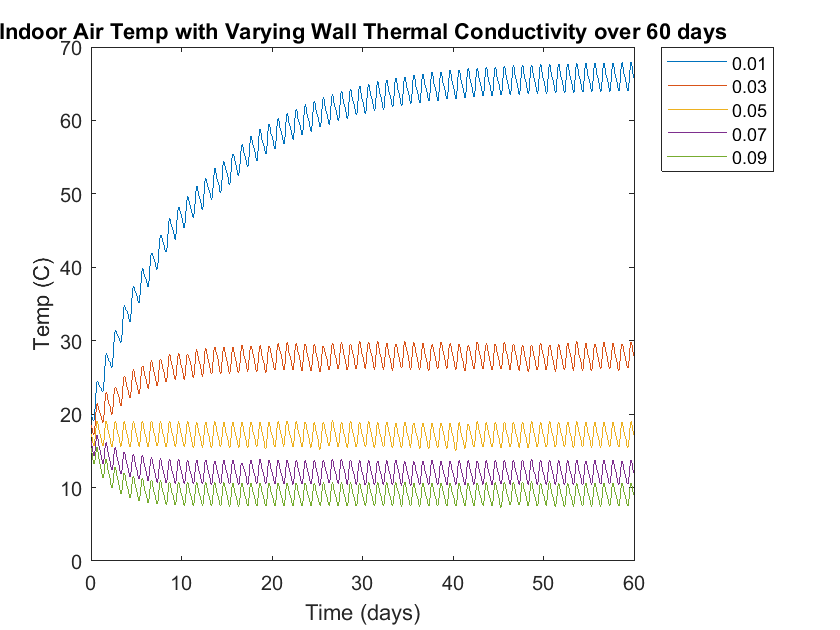

figure
for k_wall = .01:.02:.09
    TR_Wall  = L_wall/(k_wall * A_wallin);
    TR_total = TR_FloortoAir + 1/((1/(TR_AirtoWall_in + TR_Wall + TR_AirtoWall_out)) + (1/(TR_AirtoWin_in + TR_Win + TR_AirtoWin_out))); %thermal resistance

    %Refrence equations
    %q = (-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) +21 0)
    %Q_in_sun = q * A_win

    %dT_final/dt = Q_in_sun/(m_floor*c_floor) - (T_floor - T_air)/(TR_total*m_floor*c_floor);
    [t, y] = ode45(@(t,y) A_win*(-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) + 210)/(m_floor*c_floor) - (y - T_air)/(TR_total*m_floor*c_floor), tspan, y_0);

    T_air_in = ((-TR_FloortoAir.*(y - T_air))./TR_total) + y;
   

    plot(t/(60*60*24),T_air_in)
    hold on
    legend('0.01','0.03','0.05','0.07','0.09',"Location","bestoutside")
    xlabel("Time (days)")
    ylabel("Temp (C)")
    title('Indoor Air Temp with Varying Wall Thermal Conductivity over 60 days')
end

% yline(17,'g')
% yline(25, 'g')


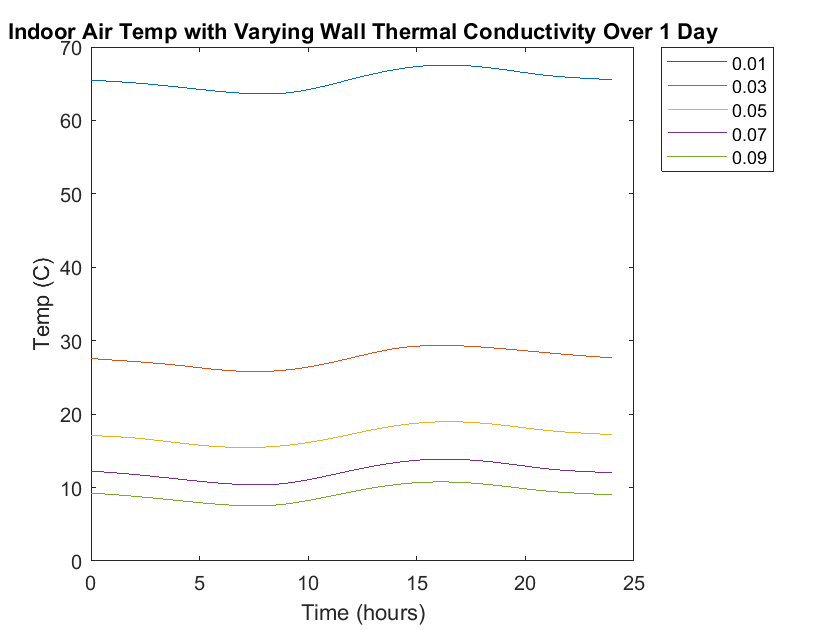


figure
for k_wall = .01:.02:.09
    TR_Wall  = L_wall/(k_wall * A_wallin);
    TR_total = TR_FloortoAir + 1/((1/(TR_AirtoWall_in + TR_Wall + TR_AirtoWall_out)) + (1/(TR_AirtoWin_in + TR_Win + TR_AirtoWin_out))); %thermal resistance

    %Refrence equations
    %q = (-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) +21 0)
    %Q_in_sun = q * A_win

    %dT_final/dt = Q_in_sun/(m_floor*c_floor) - (T_floor - T_air)/(TR_total*m_floor*c_floor);
    [t, y] = ode45(@(t,y) A_win*(-361*cos((pi*t)/(12 * 3600)) + 224*cos((pi*t)/(6 * 3600)) + 210)/(m_floor*c_floor) - (y - T_air)/(TR_total*m_floor*c_floor), tspan, y_0);

    T_air_in = ((-TR_FloortoAir.*(y - T_air))./TR_total) + y;
    
    dayfourtynine = 48*60*60*24/6;
    dayfifty = 49*60*60*24/6;

    plot((t(dayfourtynine:dayfifty)-t(dayfourtynine))/(60*60), T_air_in(dayfourtynine:dayfifty))
    hold on
    legend('0.01','0.03','0.05','0.07','0.09',"Location","bestoutside")
    xlabel("Time (hours)")
    ylabel("Temp (C)")
    title('Indoor Air Temp with Varying Wall Thermal Conductivity Over 1 Day')
end